clear; clc; close all;

output_folder = 'QAM_Plots'; 
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

N         = 50000;
SNR_range = 0:2:30;
QAM_orders = [16, 32, 64, 128, 256];   
sigma_phis = [0, 0.05, 0.15];

function sep = sep_qam_theoretical(M, snr_dB)
    snr_lin = 10.^(snr_dB / 10);

    if mod(log2(M), 2) == 0
        sep = 4*(1 - 1/sqrt(M)) .* qfunc(sqrt(3*snr_lin/(M-1))) ...
            - 4*(1 - 1/sqrt(M))^2 .* qfunc(sqrt(3*snr_lin/(M-1))).^2;
    else
        
        const    = qammod((0:M-1)', M, 'UnitAveragePower', true);
        d_min    = min_distance(const);
        N_avg    = avg_neighbors(const, d_min);
        
        sep = zeros(size(snr_lin));
        for k = 1:length(snr_lin)
            sigma = sqrt(1/(2*snr_lin(k)));
            sep(k) = min(1, N_avg * qfunc(d_min / (2*sigma)));
        end
    end
end

function d = min_distance(const)
    pts  = [real(const), imag(const)];
    dmat = pdist(pts);  
    d    = min(dmat(dmat > 1e-6));
end

function N_avg = avg_neighbors(const, d_min)
    M      = length(const);
    counts = zeros(M, 1);
    for i = 1:M
        dists      = abs(const - const(i));
        counts(i)  = sum(dists > 1e-6 & dists < d_min * 1.05);
    end
    N_avg = mean(counts);
end

function sep = sep_monte_carlo(M, N, snr_dB, sigma_phi)
    data = randi([0,M-1], 1, N);
    tx   = qammod(data, M, 'UnitAveragePower', true);

    if sigma_phi > 0
        phi = angle(exp(1j * sigma_phi * randn(size(tx))));
        tx  = tx .* exp(1j * phi);
    end

    rx      = awgn(tx, snr_dB, 'measured');
    rx_data = qamdemod(rx, M, 'UnitAveragePower', true);
    sep     = mean(rx_data ~= data);
end

results = cell(length(QAM_orders), length(sigma_phis));

Υπολογισμός SEP curves...



for i = 1:length(QAM_orders)
    M = QAM_orders(i);
    for j = 1:length(sigma_phis)
        sep_vec = zeros(1, length(SNR_range));
        for k = 1:length(SNR_range)
            sep_vec(k) = sep_monte_carlo(M, N, SNR_range(k), sigma_phis(j));
        end
        results{i,j} = sep_vec;
        fprintf('  M=%-3d  sigma=%.2f — OK\n', M, sigma_phis(j));
    end
end

  M=16   sigma=0.00 — OK
  M=16   sigma=0.05 — OK
  M=16   sigma=0.15 — OK
  M=32   sigma=0.00 — OK
  M=32   sigma=0.05 — OK
  M=32   sigma=0.15 — OK
  M=64   sigma=0.00 — OK
  M=64   sigma=0.05 — OK
  M=64   sigma=0.15 — OK
  M=128  sigma=0.00 — OK
  M=128  sigma=0.05 — OK
  M=128  sigma=0.15 — OK
  M=256  sigma=0.00 — OK
  M=256  sigma=0.05 — OK
  M=256  sigma=0.15 — OK


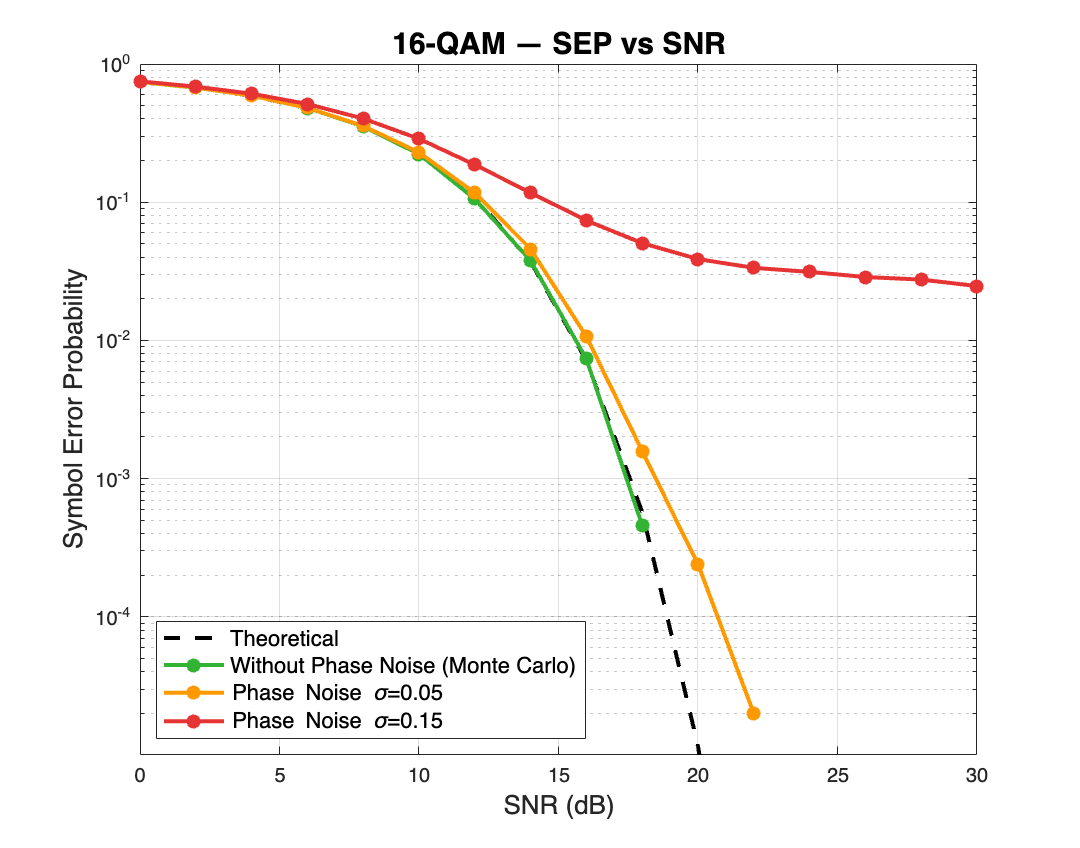

  Αποθηκεύτηκε: QAM_Plots/16QAM_SEP_vs_SNR.png


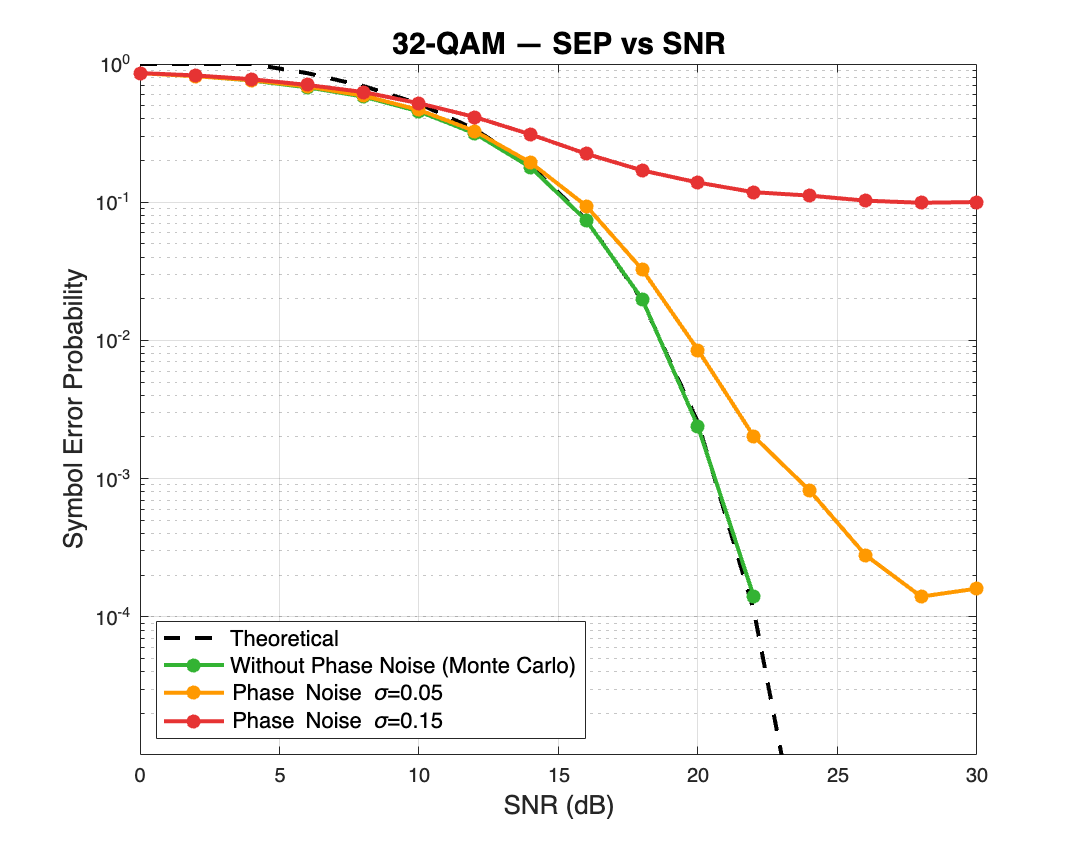

  Αποθηκεύτηκε: QAM_Plots/32QAM_SEP_vs_SNR.png


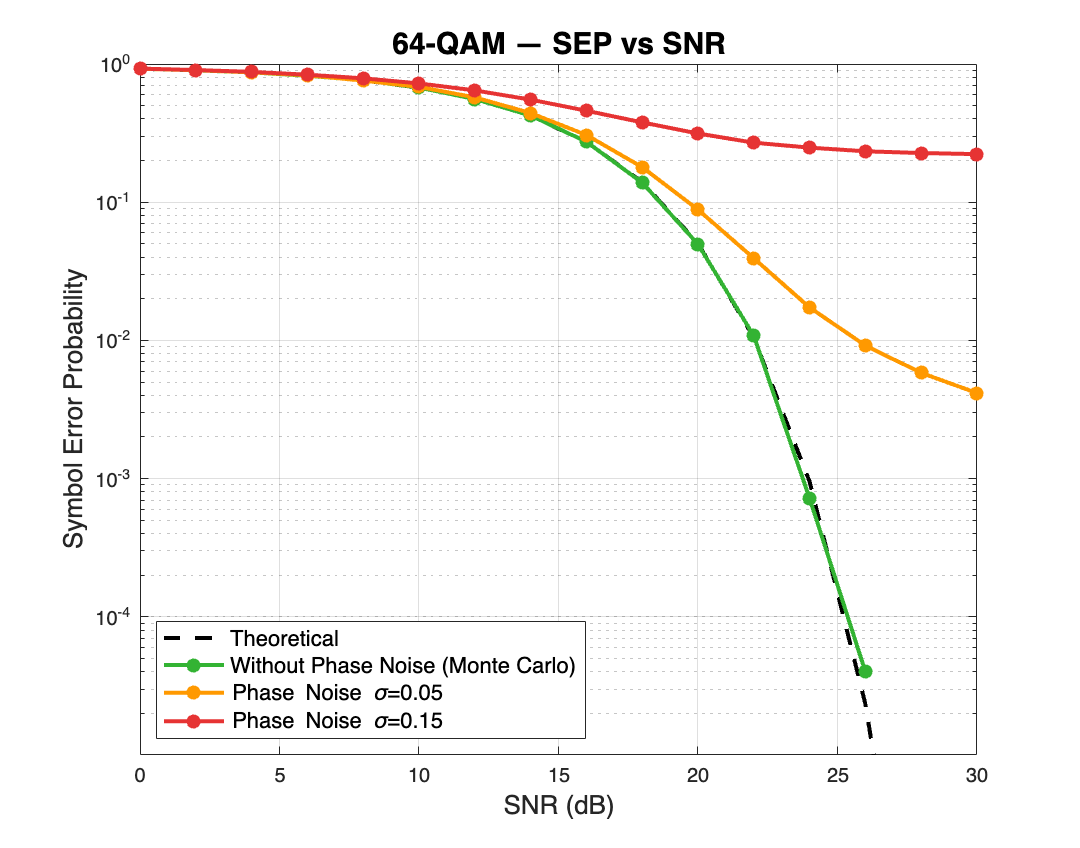

  Αποθηκεύτηκε: QAM_Plots/64QAM_SEP_vs_SNR.png


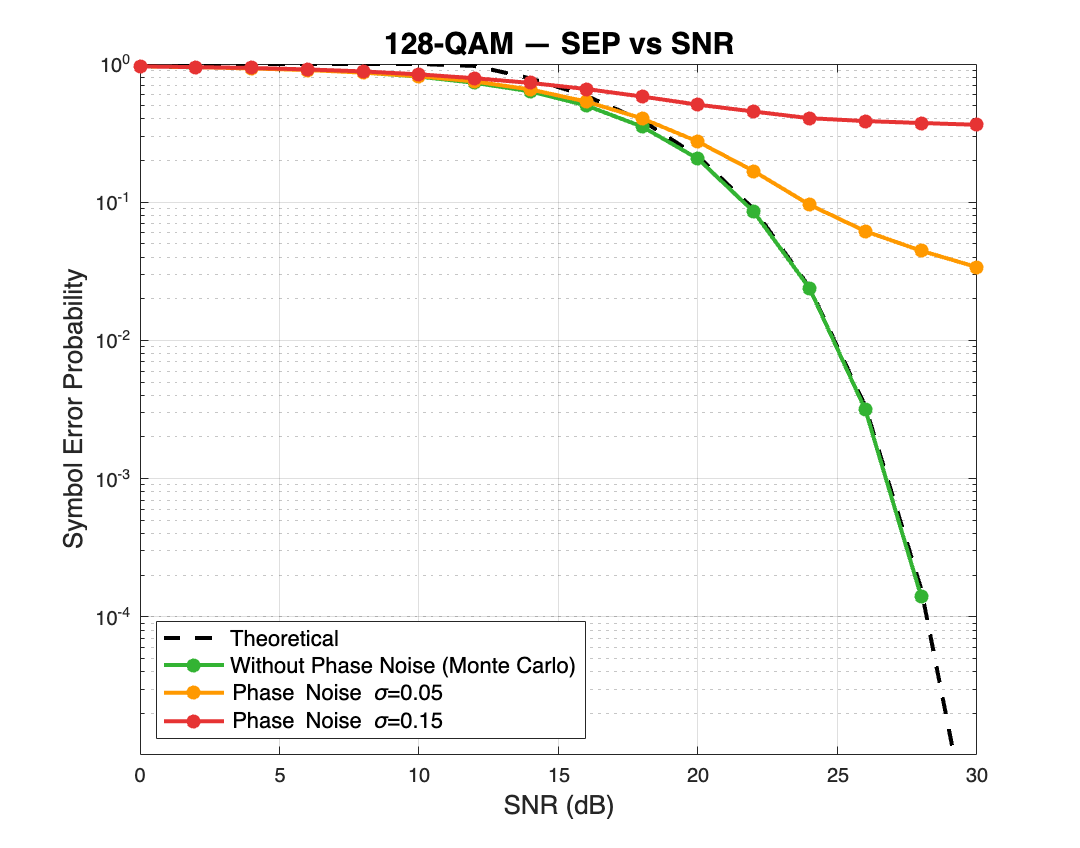

  Αποθηκεύτηκε: QAM_Plots/128QAM_SEP_vs_SNR.png


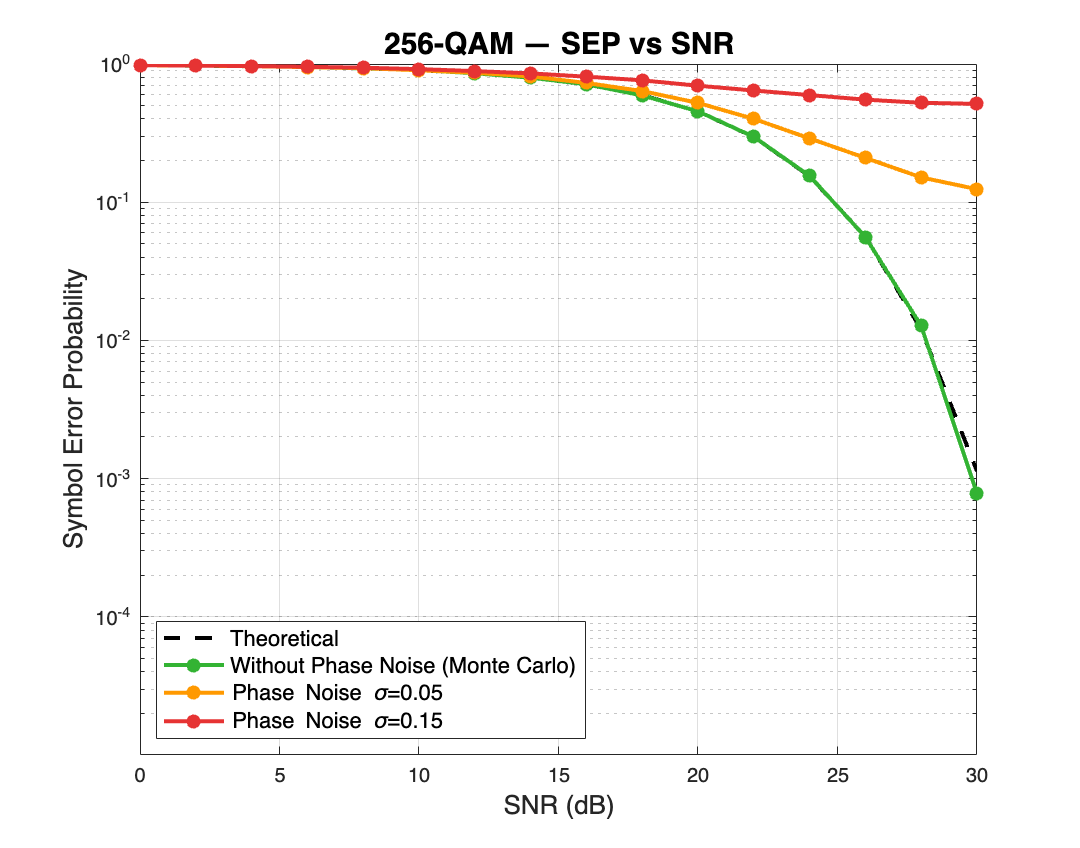

  Αποθηκεύτηκε: QAM_Plots/256QAM_SEP_vs_SNR.png



%% --- Plot 1: Ένα figure ανά QAM order ---
colors_pn = {[0.2 0.7 0.2], [1 0.6 0], [0.9 0.2 0.2]};
labels_pn = {'Without Phase Noise (Monte Carlo)', ...
             'Phase Noise \sigma=0.05', ...
             'Phase Noise \sigma=0.15'};

for i = 1:length(QAM_orders)
    M = QAM_orders(i);

    figure('Position', [100 100 700 550], 'Color', 'w');

    % Θεωρητικό
    sep_th = sep_qam_theoretical(M, SNR_range);
    semilogy(SNR_range, sep_th, 'k--', 'LineWidth', 2, ...
             'DisplayName', 'Theoretical');
    hold on;

    % Monte Carlo ανά sigma
    for j = 1:length(sigma_phis)
        sep_mc = results{i,j};
        sep_mc(sep_mc == 0) = NaN;
        semilogy(SNR_range, sep_mc, '-o', ...
                 'Color', colors_pn{j}, 'LineWidth', 2, ...
                 'MarkerSize', 5, 'MarkerFaceColor', colors_pn{j}, ...
                 'DisplayName', labels_pn{j});
    end

    title(sprintf('%d-QAM — SEP vs SNR', M), ...
          'FontSize', 15, 'FontWeight', 'bold');
    xlabel('SNR (dB)', 'FontSize', 13);
    ylabel('Symbol Error Probability', 'FontSize', 13);
    legend('Location', 'southwest', 'FontSize', 11);
    grid on; box on;
    gca.FontSize  = 11;
    gca.GridAlpha = 0.3;
    ylim([1e-5 1]);
    xlim([SNR_range(1) SNR_range(end)]);

    filename = sprintf('%dQAM_SEP_vs_SNR.png', M);
    saveas(gcf, fullfile(output_folder, filename));
    fprintf('  Αποθηκεύτηκε: %s\n', fullfile(output_folder, filename));
end

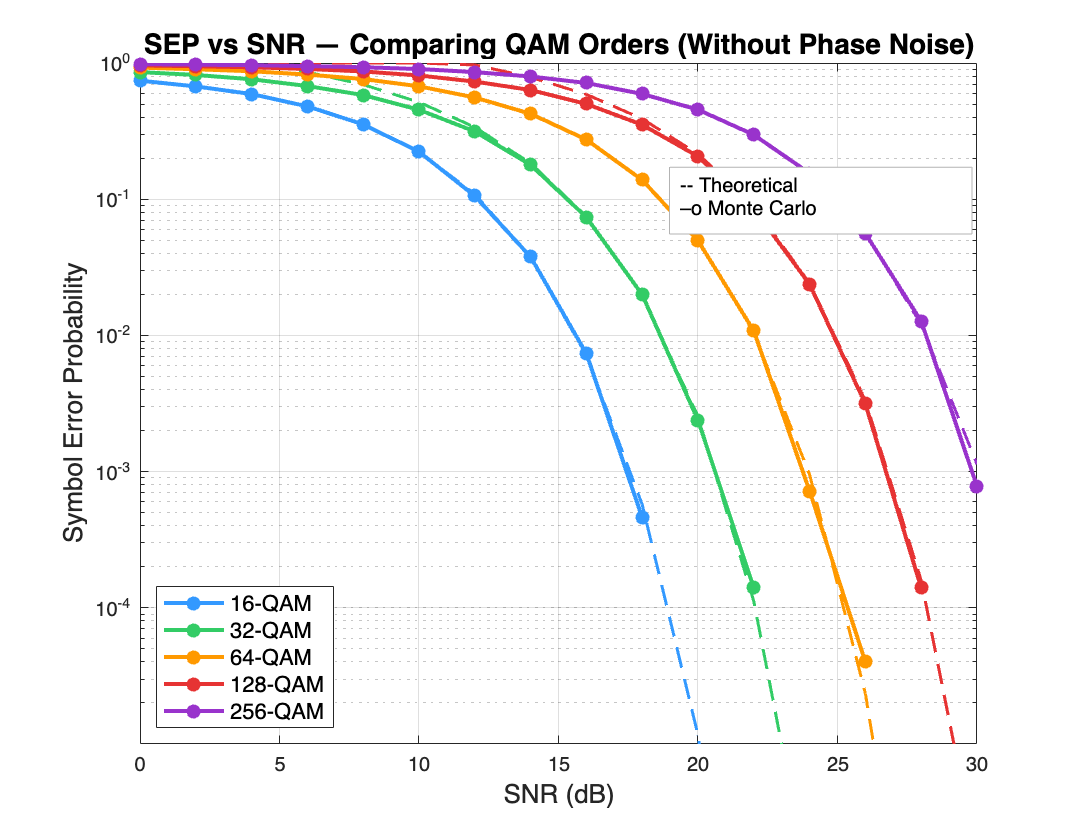


colors_qam = {[0.2 0.6 1],[0.2 0.8 0.4],[1 0.6 0],[0.9 0.2 0.2],[0.6 0.2 0.8]};

figure('Position', [100 100 750 580], 'Color', 'w');

for i = 1:length(QAM_orders)
    M     = QAM_orders(i);
    sep_t = sep_qam_theoretical(M, SNR_range);
    sep_m = results{i,1};
    sep_m(sep_m == 0) = NaN;

    semilogy(SNR_range, sep_t, '--', ...
             'Color', colors_qam{i}, 'LineWidth', 1.5, ...
             'HandleVisibility', 'off');
    hold on;
    semilogy(SNR_range, sep_m, '-o', ...
             'Color', colors_qam{i}, 'LineWidth', 2, ...
             'MarkerSize', 5, 'MarkerFaceColor', colors_qam{i}, ...
             'DisplayName', sprintf('%d-QAM', M));
end

title('SEP vs SNR — Comparing QAM Orders (Without Phase Noise)', ...
      'FontSize', 14, 'FontWeight', 'bold');
xlabel('SNR (dB)', 'FontSize', 13);
ylabel('Symbol Error Probability', 'FontSize', 13);
legend('Location', 'southwest', 'FontSize', 11);
grid on; box on;
ylim([1e-5 1]);
xlim([SNR_range(1) SNR_range(end)]);
annotation('textbox', [0.62 0.72 0.28 0.08], ...
           'String', {'-- Theoretical', '–o Monte Carlo'}, ...
           'FontSize', 10, 'EdgeColor', [0.7 0.7 0.7], ...
           'BackgroundColor', 'w');

saveas(gcf, fullfile(output_folder, 'All_QAM_SEP_comparison.png'));

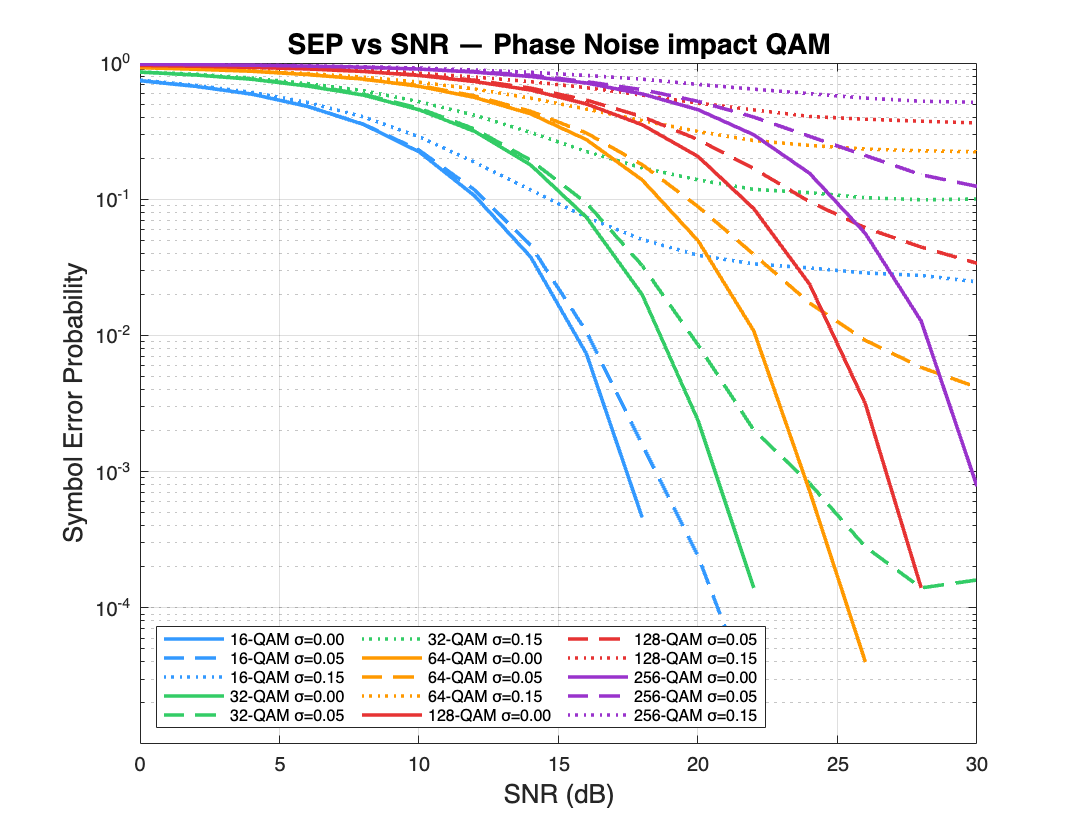

Ολοκληρώθηκε! Όλες οι εικόνες βρίσκονται στον φάκελο "QAM_Plots".



figure('Position', [100 100 750 580], 'Color', 'w');

line_styles = {'-', '--', ':'};
for i = 1:length(QAM_orders)
    for j = 1:length(sigma_phis)
        sep_mc = results{i,j};
        sep_mc(sep_mc == 0) = NaN;
        semilogy(SNR_range, sep_mc, ...
                 'LineStyle', line_styles{j}, ...
                 'Color', colors_qam{i}, ...
                 'LineWidth', 1.8, ...
                 'DisplayName', sprintf('%d-QAM σ=%.2f', QAM_orders(i), sigma_phis(j)));
        hold on;
    end
end

title('SEP vs SNR — Phase Noise impact QAM', ...
      'FontSize', 14, 'FontWeight', 'bold');
xlabel('SNR (dB)', 'FontSize', 13);
ylabel('Symbol Error Probability', 'FontSize', 13);
legend('Location', 'southwest', 'FontSize', 8, 'NumColumns', 3);
grid on; box on;
ylim([1e-5 1]);
xlim([SNR_range(1) SNR_range(end)]);

saveas(gcf, fullfile(output_folder, 'Phase_Noise_Impact_All_QAM.png'));